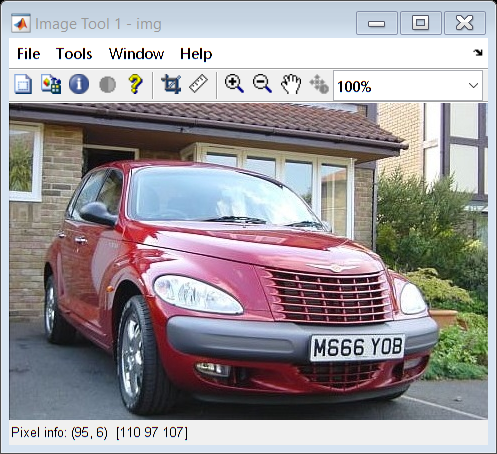

img = imread('test2.jpg');
gray = rgb2gray(img);
imtool(img);

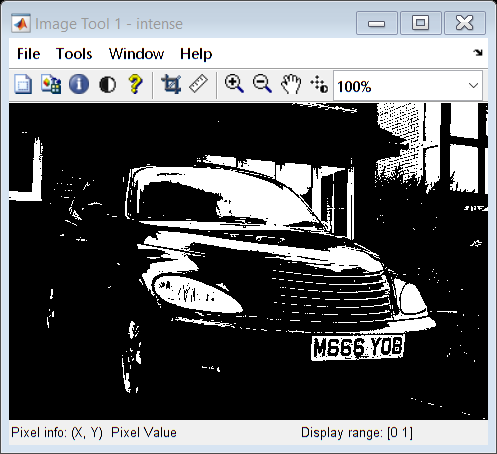

[r,c]=size(gray);
intense=zeros(r,c);
r_idx=find(gray>200);
intense(r_idx)=1;
imtool(intense);

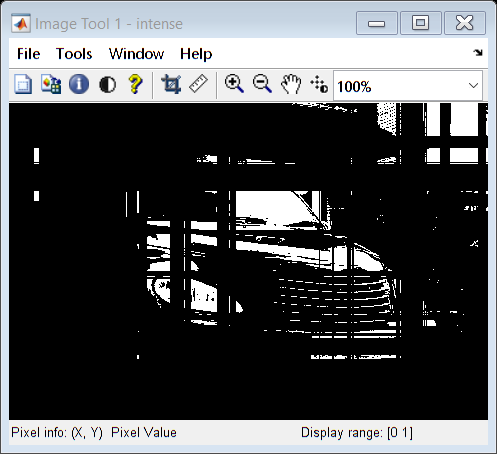

thresh_row_min = c/8;
thresh_row_max = c/3;

thresh_col_min = 25;
thresh_col_max = c/8;

for row = 1:r
    num_white = sum(intense(row,:));
    if num_white<thresh_row_min | num_white>thresh_row_max
        intense(row,:) = 0;
    end
end

for col = 1:c
    num_white = sum(intense(:,col));
    if num_white<thresh_col_min | num_white>thresh_col_max
        intense(:,col) = 0;
    end 
end

imtool(intense)

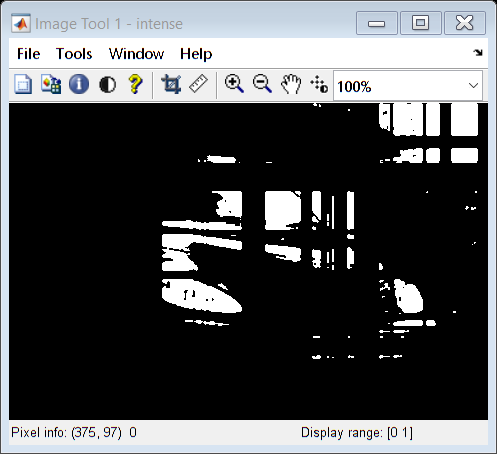

intense = medfilt2(intense,[3,3]);
imtool(intense)

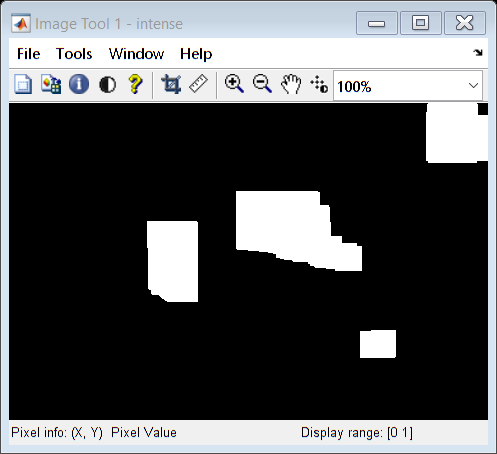

intense = medfilt2(intense,[3,3]);

se_open = strel('square',25);
se_close = strel('square',25);
intense = imclose(intense,se_close);
intense = imopen(intense,se_open);
intense = imclose(intense,se_close);
imtool(intense)

box = regionprops(intense, 'BoundingBox');
box = round(box.BoundingBox);
left=box(1);
top=box(2);
width=box(3);
height=box(4);

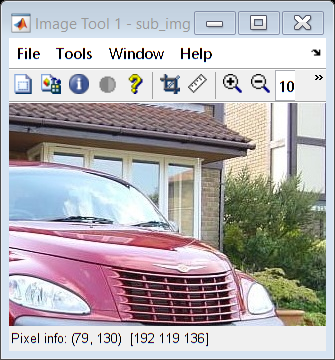

mask = zeros(r,c);
sub_img = img(top:top+height-1, left:left+width,:);
imtool(sub_img);